# Análisis de sensibilidad e incertidumbre usando matemática simbólica

## Preparación previa 

1. Definir los estados y los parámetros del modelo 

syms N1(t) N2(t) 
syms r1 r2 k1 k2 alpha12 alpha21

2. Se definen las ecuaciones 

ode1 = diff(N1) == r1 * N1 * (1 - (N1 + alpha12 * N2)/k1);
ode2 = diff(N2) == r2 * N2 * (1 - (N2 + alpha21 * N1)/k2);

odes = [ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}N_{1}\left(t\right)=-r_{1}\,N_{1}\left(t\right)\,\left(\frac{N_{1}\left(t\right)+\alpha_{12}\,N_{2}\left(t\right)}{k_{1}}-1\right)\\ \frac{\partial }{\partial t}N_{2}\left(t\right)=-r_{2}\,N_{2}\left(t\right)\,\left(\frac{N_{2}\left(t\right)+\alpha_{21}\,N_{1}\left(t\right)}{k_{2}}-1\right) \end{array}\right)$$

var = [N1 N2];

3. Definir el tiempo de simulación

domain = [0 20];

4. Utilizar la función gsua_dataprep para determinar orden de ingreso de los intervalos de los factores (parámetros y condiciones iniciales).

ModelName = 'CompetenciaSYM';
gsua_dataprep(odes, var, domain, ModelName);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccc} N_{1}\left(t\right) & N_{2}\left(t\right) & \alpha_{12} & \alpha_{21} & k_{1} & k_{2} & r_{1} & r_{2} \end{array}\right)$$

5. Ingresar los intervalos de los factores de acuerdo al orden anteriormente mencionado

Ranges = [2 100;       %N1(0)
         2 200;       %N2(0)
         0.2 0.5;     %alpha12
         0.3 0.4;     %alpha21
         200 300;     %k1
         5 200        %k2
         5 6;         %r1
         2 3;         %r2
         ];

6. Creación del objeto tipo tabla que se utilizará para hacer la estimación de parámetros 

[T, solver] = gsua_dataprep(odes, var, domain, ModelName, 'Range', Ranges);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccc} N_{1}\left(t\right) & N_{2}\left(t\right) & \alpha_{12} & \alpha_{21} & k_{1} & k_{2} & r_{1} & r_{2} \end{array}\right)$$

## Análisis de incertidumbre

1.  Definición de los conjuntos de parámetros a revisar (matriz M)

N = 100;  %número de simulaciones

2. Definir las salidas del modelo que se desean observar

T.Properties.CustomProperties.output = [1,2];

3. Correr el análisis de incertidumbre

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 15:5:10
Number of simulations: 100


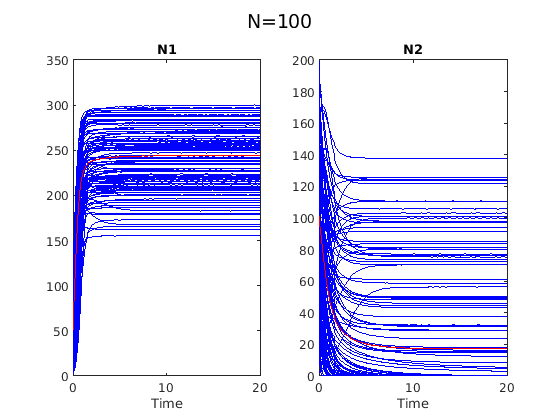

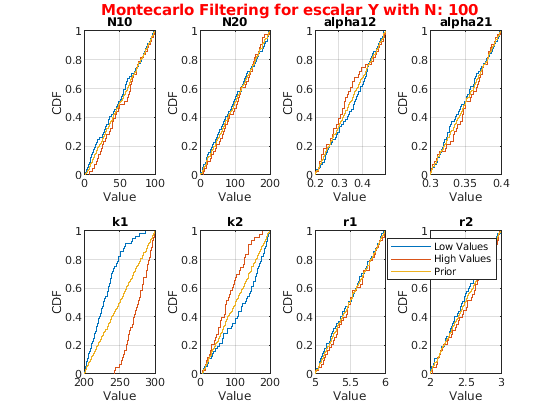

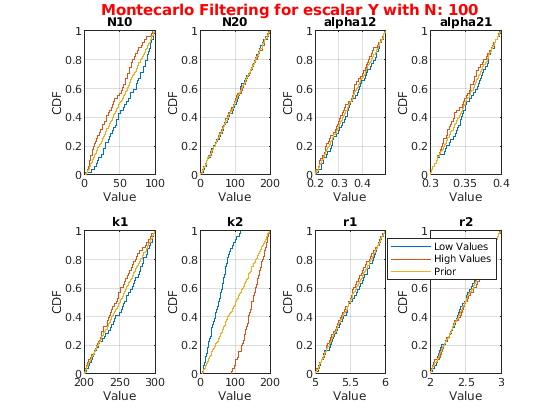

M = gsua_dmatrix(T, N, 'Method', 'Sobol');
gsua_ua(M, T, 'xdata', xdata);

## Análisis de sensibilidad

1. Definir la salida que se desea observar

T.Properties.CustomProperties.output = 1;

2. Definición de los conjuntos de parámetros a revisar (matriz M)

N = 100; %número de simulaciones
M = gsua_dmatrix(T, N, 'Method', 'Sobol');

3. Correr análisis de sensibilidad

T = gsua_sa(M, T, 'SensMethod', 'Xiao', 'xdata', xdata);

Progress: 10%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:7
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 15:5:28
Number of simulations: 5000
Progress: 20%
Estimated processing time (h:m:s): 0:0:7
Remaining time (h:m:s): 0:0:5
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 15:5:26
Number of simulations: 5000
Progress: 30%
Estimated processing time (h:m:s): 0:0:6
Remaining time (h:m:s): 0:0:4
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 15:5:25
Number of simulations: 5000
Progress: 40%
Estimated processing time (h:m:s): 0:0:6
Remaining time (h:m:s): 0:0:4
Elapsed time (h:m:s): 0:0:2
Estimated stop time (h:m:s): 15:5:26
Number of simulations: 5000
Progress: 50%
Estimated processing time (h:m:s): 0:0:6
Remaining time (h:m:s): 0:0:3
Elapsed time (h:m:s): 0:0:3
Estimated stop time (h:m:s): 15:5:26
Number of simulations: 5000
Progress: 60%
Estimated processing time (h:m:s): 0:0:6
Remaining time (h:m:s): 0:0:2
Elapsed time (h:m:s): 0:0

4. Identificar si se realizaron suficientes simulaciones para el análisis de sensibilidad (el valor debe dar cercano a 1) 

sum(T.Si)/sum(abs(T.Si))

5. Graficar los indices de sensibilidad para analizar el resultado

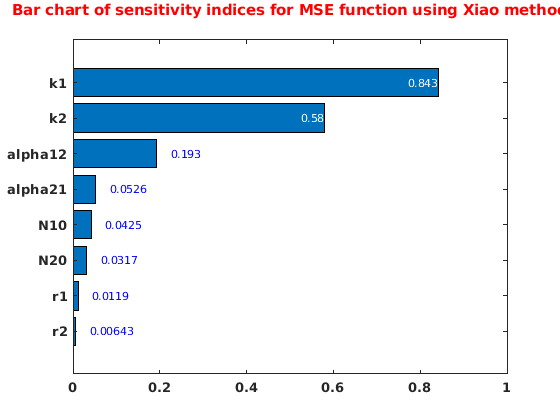

figure
gsua_plot('Bar', T, T.STi)

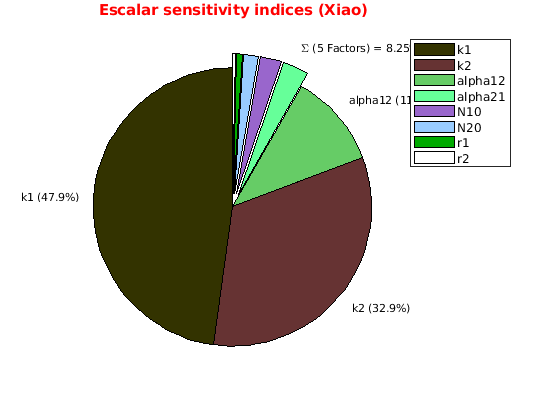

figure
gsua_plot('Pie',T, T.STi)

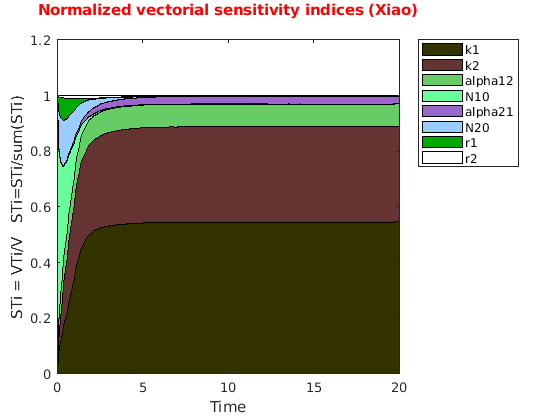

figure
gsua_plot('TotalSensitivityArea', T, T.STi_vec, xdata);